## Bias-variance trade-off in regularised polynomial regression

Illustrate the variation of polynomial order as well as the ridge regression parameter to illustrate the bias-variance trade-off

clear
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);

Generate the sine wave function with one example data set

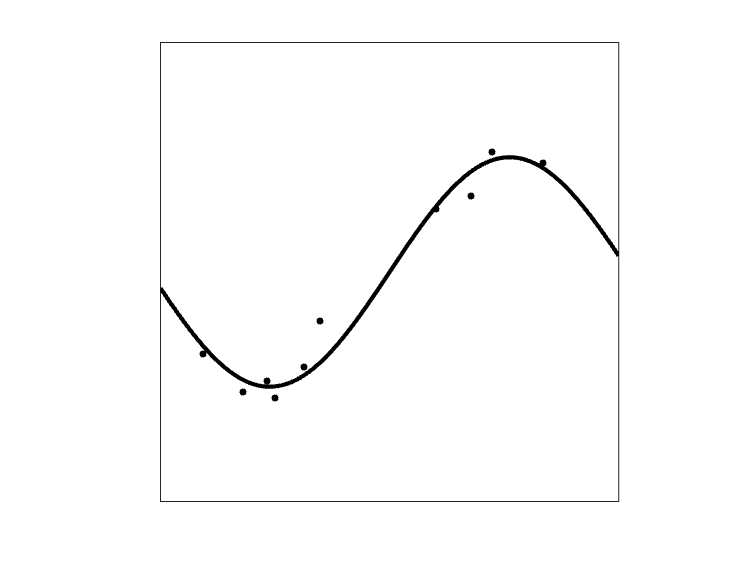

rng(1)

N = 10;     % Observations per training set
M = 500;   % Number of training sets
C = cvpartition(N*M, 'KFold', M);

xFull = 2*rand(N*M,1) - 1;
yFullSine = sin(3*xFull) + 0.2*randn(N*M,1);

xVec = linspace(-1,1)';
figure
i = 1;
x = xFull(C.test(i));
y = yFullSine(C.test(i));
    
p = plot(xVec, sin(3*xVec), 'k', ...
         x, y, 'k.','MarkerSize',10, 'LineWidth', 2);
axis([-1 1 -2 2])
axis square
a = gca(); a.XTick = []; a.YTick = [];

Fit a straight line to the data

P = 1;

theta_sine = zeros(P+1,M);
for i = 1:M
    % Select data and create the design matrix
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    X = ones(N,P+1);
    for j = 1:P
        X(:,j+1) = x.^j;
    end

    % Fit the straight line to the data
    theta_sine(:,i) = (X'*X)\(X'*y);
end

Draw multiple straight line fits to the data

figure

% Design matrix for fitted line
XVec = ones(length(xVec),P+1);
for j = 1:P
    XVec(:,j+1) = xVec.^j;
end 

for i = 1:M/10
    % Select the data
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    
    % Plot the fitted line
    p = plot(xVec, XVec*theta_sine(:,1:i), ...
             xVec, sin(3*xVec), ...
             x, y, 'k.','MarkerSize',10);
    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(1,:);
    end
    p(i).LineWidth = 2; p(i).Color = 0.7*newcolor(1,:);
    p(i+1).LineWidth = 2; p(i+1).Color = 'k';
    axis([-1 1 -2 2])
    axis square
    a = gca(); a.XTick = []; a.YTick = [];

    drawnow

end

Fit a polynomial to the data

P = 7;  % Polynomial order
theta_sine = zeros(P+1,M);
for i = 1:M
    % Select data and create the design matrix
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    X = ones(N,P+1);
    for j = 1:P
        X(:,j+1) = x.^j;
    end

    % Fit the polynomial to the data
    theta_sine(:,i) = (X'*X)\(X'*y);
end

Draw the fitted lines

figure

% Design matrix for fitted line
XVec = ones(length(xVec),P+1);
for j = 1:P
    XVec(:,j+1) = xVec.^j;
end 

for i = 1:M/10
    % Select the data
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    
    % Plot the fitted lines
    p = plot(xVec, XVec*theta_sine(:,1:i), ...
             xVec, sin(3*xVec), ...
             x, y, 'k.','MarkerSize',10);
    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    p(i).LineWidth = 2; p(i).Color = 0.7*newcolor(2,:);
    p(i+1).LineWidth = 2; p(i+1).Color = 'k';
    axis([-1 1 -2 2])
    axis square
    a = gca(); a.XTick = []; a.YTick = [];

    drawnow

end

Calculate the MSE as a function of the polynomial order

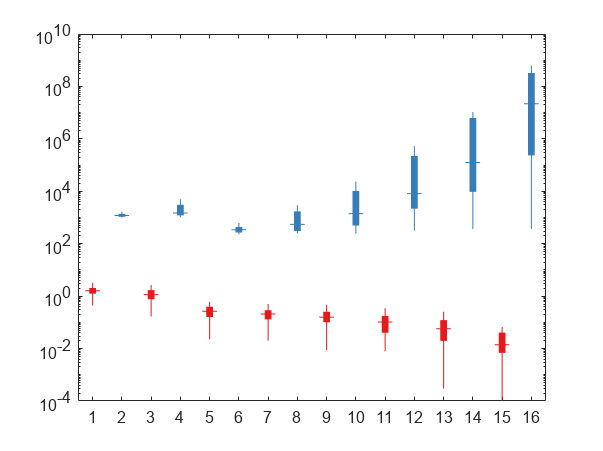

PP = N-2;
MSE_sine = zeros(M/10,PP);
MSE_train = zeros(M/10,PP);
data = []; group = [];

for P = 1:PP
    
    theta_sine = zeros(P+1,M);
    
    for i = 1:M/10
        % Select data
        x = xFull(C.test(i));
        y = yFullSine(C.test(i));
        Ytest = yFullSine(C.training(i));
        
        % Create design matrix for training and testing data
        X = ones(N,P+1);
        Xtest = ones((M-1)*N,P+1);
        for j = 1:P
            X(:,j+1) = x.^j;
            Xtest(:,j+1) = xFull(C.training(i)).^j;
        end
    
        % Fit ordinary LSQ for current polynomial order
        theta_sine(:,i) = (X'*X)\(X'*y);
        
        % Calculate MSE on current training and testing data
        MSE_train(i,P) = sum( (y - X*theta_sine(:,i)).^2 );
        MSE_sine(i,P) = sum( (Ytest - Xtest*theta_sine(:,i)).^2 );
    end
    data = [data MSE_train(:,P) MSE_sine(:,P)];
    group = [group 0 1];
end

% Boxplot of the MSE using both training and testing data
boxplot(data, 'ColorGroup', group,...
        'Symbol','','boxstyle','filled','Colors',newcolor([1,2],:));
a = gca(); a.YScale = 'log'; a.YLim = [1e-4 1e10]; a.YTick = 10.^(-4:2:10);

Show a dats set with the generating function, then with the ordinary LSQ estimate added, and finally with the ridge regression estimate included as well

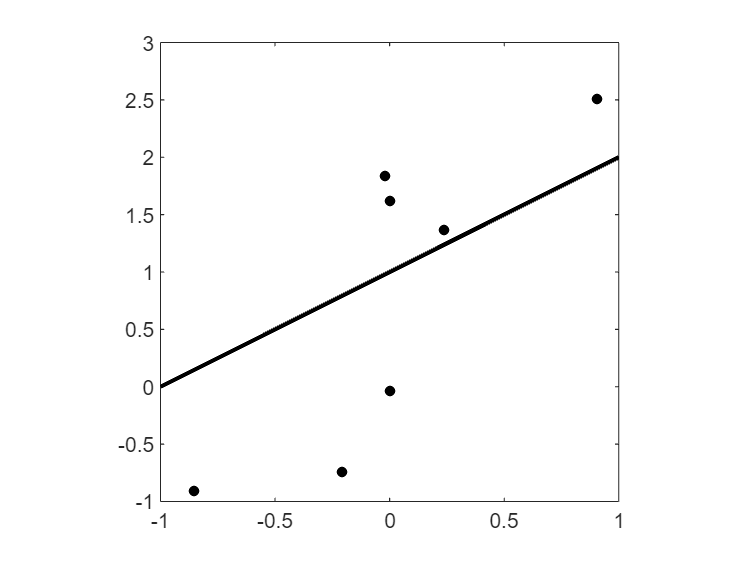

m = 1;
c = 1;

rng(1)
i = 4;
yFull = m*xFull + c + 1.5*randn(N*M,1);
x = xFull(C.test(i));
y = yFull(C.test(i));   

X = [x ones(N,1)];
theta(:,1) = (X'*X)\(X'*y);
theta_reg(:,1) = (X'*X + 3*eye(2))\(X'*y);

figure
plot(x,y,'k.', [-1 1], [-1 1; 1 1]*[m;c],...
    'k','LineWidth',2,'MarkerSize',15)
axis([-1 1 -1 3])
axis square

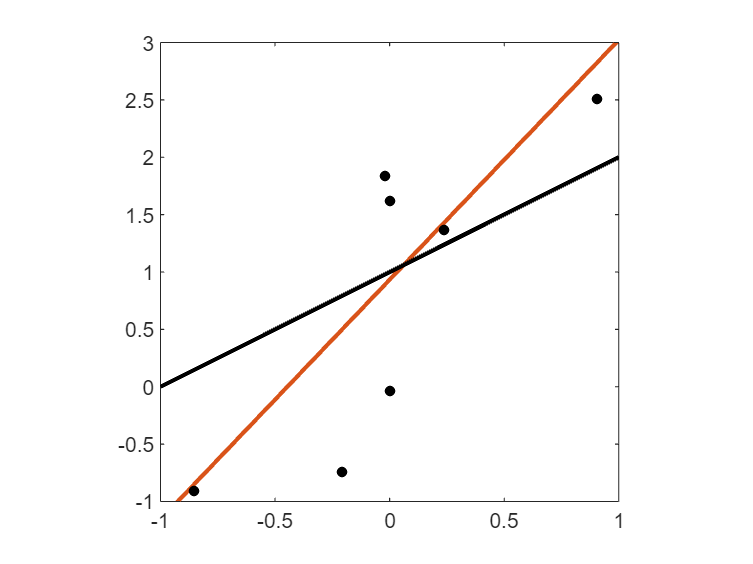


figure
plot([-1],[-1],[-1 1], [-1 1; 1 1]*theta(:,1),...
     x,y,'k.', [-1 1], [-1 1; 1 1]*[m;c],...
    'k','LineWidth',2,'MarkerSize',15)
axis([-1 1 -1 3])
axis square

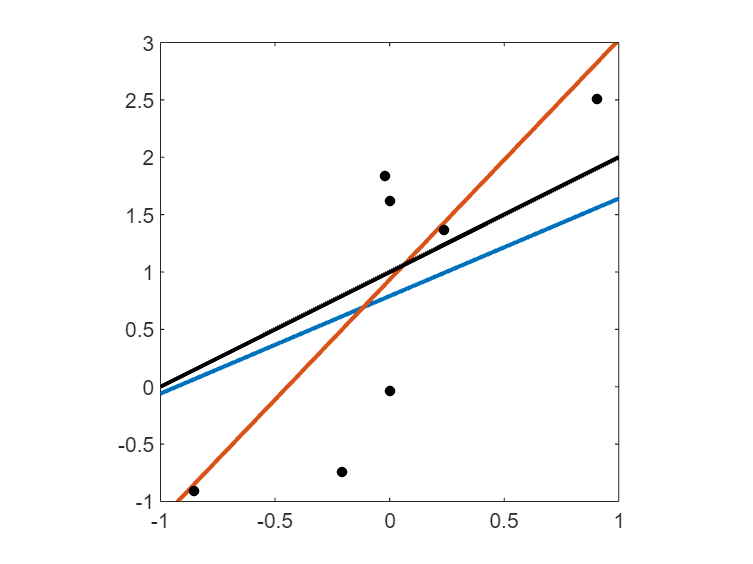


figure
plot([-1 1], [-1 1; 1 1]*theta_reg(:,1),...
     [-1 1], [-1 1; 1 1]*theta(:,1),...
     x,y,'k.', [-1 1], [-1 1; 1 1]*[m;c],...
    'k','LineWidth',2,'MarkerSize',15)
axis([-1 1 -1 3])
axis square

Fit the parameters using ordinary LSQ and ridge regression. Estimate the prediction error and store the values for later use

theta = zeros(2,M);
theta(:,1) = [m;c];
theta_reg = theta;

for i = 2:M
    % Select the data
    x = xFull(C.test(i));
    y = yFull(C.test(i));
    
    % Fit the models
    X = [x ones(N,1)];
    theta(:,i) = (X'*X)\(X'*y);
    theta_reg(:,i) = (X'*X + 3*eye(2))\(X'*y);

    % Calculate MSE
    MSE(i,1) = sum( (theta(:,i) - [m; c]).^2 );
    MSE_reg(i,1) = sum( (theta_reg(:,i) - [m; c]).^2 );
    
end

Plot the fitted lines estimated using ordinary LSQ and ridge regression

skip = 10;
figure
for i = 2:skip:M
    % Select a data set
    x = xFull(C.test(i));
    y = yFull(C.test(i));

    % Plot the data and the fitted lines
    subplot(2,2,1)
    p = plot([-1 1], [-1 1; 1 1]*theta(:,1:skip:i), ...
             [-1 1], [-1 1; 1 1]*theta_reg(:,1:skip:i), ...
             [-1 1], [-1 1; 1 1]*theta(:,1),...
             x, y, 'k.','MarkerSize',10);
    pN = length(p); pNN = (pN-2)/2;
    for j = 1:pNN
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    for j = pNN+1:2*pNN
        p(j).LineWidth = 0.5; p(j).Color = newcolor(1,:);
    end
    p(end-3).LineWidth = 2; p(end-2).Color = 0.8*newcolor(2,:);
    p(end-2).LineWidth = 2; p(end-1).Color = 0.8*newcolor(1,:);
    p(end-1).LineWidth = 2; p(end-1).Color = 'k';
    p(end).LineWidth = 2; p(end).Color = 'k';
    axis([-1 1 -1 3])
    axis square
    
    % Plot the estimated parameters in the parameter space
    subplot(2,2,3)
    pt = plot(theta_reg(1,1:i), theta_reg(2,1:i), '.',...
              theta(1,1:i), theta(2,1:i), '.', ...
              theta(1,[1, i]), theta(2,[1, i]), '-o',...
              theta_reg(1,[1, i]), theta_reg(2,[1, i]), '-o', ...
              m, c, '.');
    pt(1).MarkerSize = 5; 
    pt(2).MarkerSize = 5; 
    pt(3).MarkerSize = 5; pt(3).MarkerFaceColor = newcolor(2,:); pt(3).LineWidth = 2; pt(3).Color = newcolor(2,:);
    pt(4).MarkerSize = 5; pt(4).MarkerFaceColor = newcolor(1,:); pt(4).LineWidth = 2; pt(4).Color = newcolor(1,:);
    pt(5).MarkerSize = 20; pt(5).MarkerFaceColor = 'k'; pt(5).Color = 'k';
    axis([-2 4 -2 4])
    axis square
    
    % Plot the CDF of the error between the true and estimated parameters
    % Error for ordinary LSQ estimated parameters
    subplot(2,2,2)
    bh = barh((1:i)/i, sort(MSE(1:i)),'FaceColor',newcolor(2,:));
    bh.EdgeColor = 'none';
    axis([0 2.4 0 1])

    % Error for ridge regression estimated parameters
    subplot(2,2,4)
    bh = barh((1:i)/i, sort(MSE_reg(1:i)),'FaceColor',newcolor(1,:));
    bh.EdgeColor = 'none';
    axis([0 2.4 0 1])

    drawnow

end

Plot the gamma distribution and CDF for the ordinary LSQ and regularised parameters, respectively

mu = mean(MSE)

mu = 1.0480

mu_reg = mean(MSE_reg)

mu_reg = 0.6568


x = sort(MSE);
x_reg = sort(MSE_reg);

edges = linspace(0, 2.5, 100);
histMSE = histcounts(MSE, edges,'Normalization','pdf');
histMSE_reg = histcounts(MSE_reg, edges,'Normalization','pdf');

y = (1:M)'/M;
fLSQ = @(p, x) (y - gamcdf(x, p(1), p(2)));

p = lsqnonlin(@(p) fLSQ(p, x), [0.9; 0.8]);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


p_reg = lsqnonlin(@(p) fLSQ(p, x_reg), [1.1; 0.45]);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


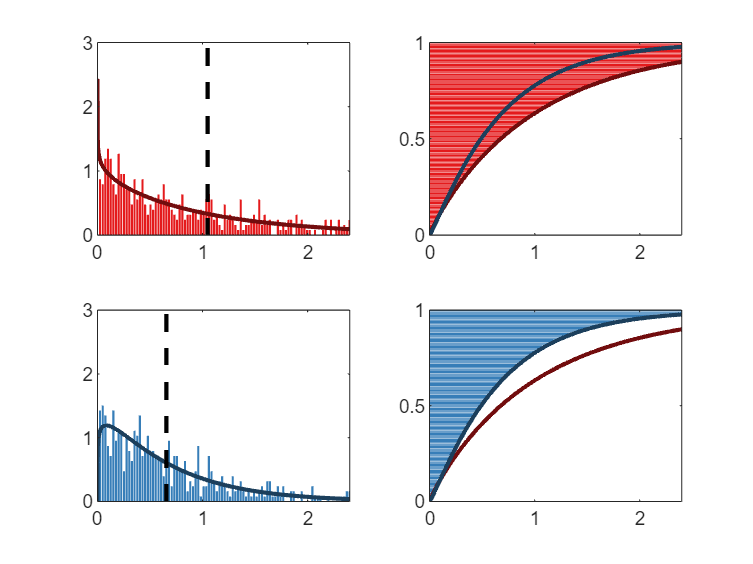


figure
subplot(2,2,2)
bh = barh((1:i)/i, x,'FaceColor', newcolor(1,:));
hold on
plot(x, gamcdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot(x, gamcdf(x, p_reg(1), p_reg(2)),'Color', 0.5*newcolor(2,:),'LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,4)
bh = barh((1:i)/i, x_reg,'FaceColor',newcolor(2,:));
hold on
plot(x, gamcdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot(x, gamcdf(x, p_reg(1), p_reg(2)),'Color', 0.5*newcolor(2,:),'LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,1)
bh = bar(edges(2:end), histMSE, 'FaceColor', newcolor(1,:));
hold on
plot(x, gampdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot([mu mu], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])

subplot(2,2,3)
bh = bar(edges(2:end), histMSE_reg, 'FaceColor', newcolor(2,:));
hold on
plot(x_reg, gampdf(x_reg, p_reg(1), p_reg(2)), 'Color', 0.5*newcolor(2,:),'LineWidth',2)
plot([mu_reg mu_reg], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])

Show how the probability distribution over the $\left(m,c\right)$ parameter space varies with $\lambda \;$

figure
L = 50; % Number of lambda values to check
theta_reg_scan = zeros(2,M,L);
lambda_scan = logspace(-1,2,L);
MSE_reg_scan = zeros(M, L);
for j = 1:L
    for i = 1:M
        % Select data
        x = xFull(C.test(i));
        y = yFull(C.test(i));
        X = [x ones(N,1)];

        % Fit regularised least squares and calculate MSE
        theta_reg_scan(:,i,j) = (X'*X + lambda_scan(j)*eye(2))\(X'*y);
        MSE_reg_scan(i,j) = sum( (theta_reg_scan(:,i,j) - [m; c]).^2 );
    end
    
    % Calculate the mean and covariance of the fitted parameters for a
    % given lambda value
    mu_scan(:,j) = mean(theta_reg_scan(:,:,j)')';
    sigma_scan(:,:,j) = cov(theta_reg_scan(:,:,j)');
end


Plot the constant probability density contour representing the MVN distribution of the regularised parameters $\left(\hat{m\;} ,\hat{\;c} \right)$

locus = linspace(0,2*pi);
for j = [1:L, L:-1:1]
    
    % Plot parameter space
    subplot(2,1,1)
    
    ellips0 = 3*sigma_scan(:,:,1)*[cos(locus); sin(locus)]; % lambda = 0 ellipse
    ellips = 3*sigma_scan(:,:,j)*[cos(locus); sin(locus)];  % varying lambda ellipse

    % Plot set of fitted parameters for varying lambda, and the bounding
    % ellipse
    p = plot(theta_reg_scan(1,:,j), theta_reg_scan(2,:,j),'.', ...
             [m mu_scan(1,j)], [c mu_scan(2,j)], '-o',...
             mu_scan(1,1) + ellips0(1,:), mu_scan(2,1) + ellips0(2,:),'k',...
             mu_scan(1,j) + ellips(1,:), mu_scan(2,j) + ellips(2,:),'k',...
             [-2 4 0 0 0], [0 0 0 -2 4], 'k');
    p(2).MarkerSize = 2; p(2).Color = 'k'; p(2).LineWidth = 2;
    axis([-2 4 -2 4]); axis square
    a = gca(); a.XTick = []; a.YTick = [];
    
    % Plot the MSE as a function of lambda, and identify the current lambda
    subplot(2,1,2)
    p = semilogx(lambda_scan(j), mean(MSE_reg_scan(:,j)),'.', ...
           lambda_scan, mean(MSE_reg_scan),'k',...
           lambda_scan, prctile(MSE_reg_scan, 5),'k',...
           lambda_scan, prctile(MSE_reg_scan, 95),'k',...
           'MarkerSize',25);
    p(2).LineWidth = 2;
    p(3).LineWidth = 0.5;
    p(4).LineWidth = 0.5;
    a = gca(); a.XTick = 10.^(-1:2); a.YTick = [];
    axis square
    
    drawnow

end

Calculate the prediction error over a range of $\lambda \;$values for a fixed polynomial order `P`

rng(1)

P = 7;
lambda_scan = logspace(-3,0,L); % Lambda values to evaluate

theta_sine = zeros(P+1,M);
theta_reg_sine = theta_sine;
for i = 1:M
    % Select the data set
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    Ytest = yFullSine(C.training(i));
    
    % Create design matrix for training and testing
    X = ones(N,P+1);
    Xtest = ones((M-1)*N,P+1);
    for j = 1:P
        X(:,j+1) = x.^j;
        Xtest(:,j+1) = xFull(C.training(i)).^j;
    end
    
    % Fit ordinary LSQ and calculate the prediction error
    theta_sine(:,i) = (X'*X)\(X'*y);
    MSE_sine(i,1) = sum( (Ytest - Xtest*theta_sine(:,i)).^2 );
    
    % Fit ridge regression with varying lambda, 
    % and calculate the prediction error
    for j = 1:L
        theta_reg_sine(:,i,j) = (X'*X + lambda_scan(j)*eye(P+1))\(X'*y);
        MSE_reg_sine(i,j) = sum( (Ytest - Xtest*theta_reg_sine(:,i,j)).^2 );
    end
end


Plot the MSE vs $\lambda \;$, including 5% and 95% percentile lines

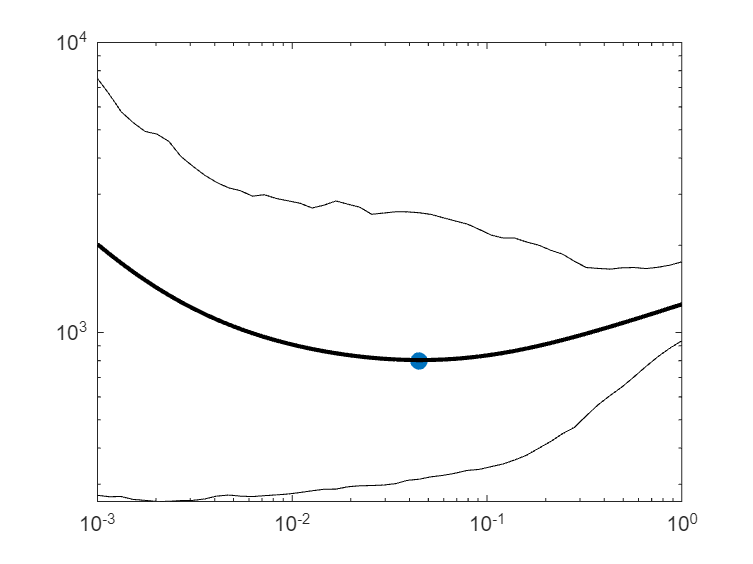

figure
[~, I] = min(mean(MSE_reg_sine));
p = loglog(lambda_scan(I), mean(MSE_reg_sine(:,I)),'.', ...
           lambda_scan, mean(MSE_reg_sine),'k',...
           lambda_scan, prctile(MSE_reg_sine, 5),'k',...
           lambda_scan, prctile(MSE_reg_sine, 95),'k',...
           'MarkerSize',25);
p(2).LineWidth = 2;

p(3).LineWidth = 0.5;
p(4).LineWidth = 0.5;


Plot the different fits obtained using the regularised and non-regularised polynomial as an animation

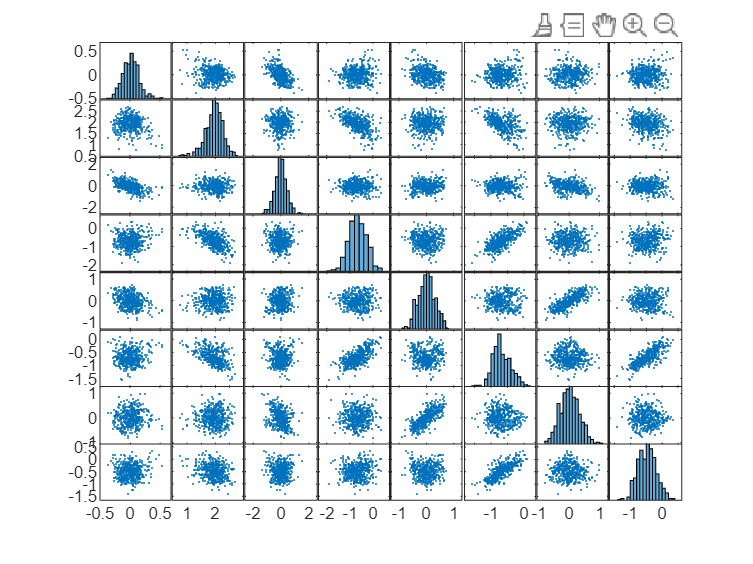

figure
xVec = linspace(-1,1)';
XVec = ones(length(xVec),P+1);
for j = 1:P
    XVec(:,j+1) = xVec.^j;
end    
for i = 1:M/10
    % Select data (regression already performed previously)
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    
    % Plot the LSQ as well as Ridge Regression fit, as well as the data
    p = plot(xVec, XVec*theta_sine(:,1:i), ...
             xVec, XVec*theta_reg_sine(:,1:i, I),...
             xVec, sin(3*xVec), ...
             x, y, 'k.','MarkerSize',10);
    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    for j = i+1:2*i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(1,:);
    end
    p(i).LineWidth = 2; p(i).Color = 0.7*newcolor(2,:);
    p(2*i).LineWidth = 2; p(i+1).Color = 0.7*newcolor(1,:);
    p(2*i+1).LineWidth = 2; p(2*i+1).Color = 'k';
    axis([-1 1 -2 2])
    axis square
    
    drawnow

end


Show statistical properties of the regularised polynomial fit, determined in the previous section

plotmatrix(theta_reg_sine(:,:,I)')

Use the bootstrap to estimate the statistical properties of the 8 parameters used when fitting the regularised 7th order polynomial to the sine wave data

% Select the data set to perform the bootstrap on
i = 3;
xSelected = xFull(C.test(3));
ySelected = yFullSine(C.test(3));

% Perform bootstrap for the polynomial regression
rng(1)
BN = 1000;
theta_boot_sine = zeros(P+1,BN);
idx = zeros(BN, length(xSelected));
for i = 1:BN
    idx(i,:) = randsample(length(xSelected), length(xSelected), true);
    x = xSelected(idx(i,:));
    y = ySelected(idx(i,:));
    
    X = ones(length(xSelected),P+1);
    for j = 1:P
        X(:,j+1) = x.^j;
    end
    theta_boot_sine(:,i) = (X'*X + 0.045*eye(P+1))\(X'*y);
end

Plot the sampled data and the fitted polynomial, clearly showing which data points were selected during the current bootstrap run

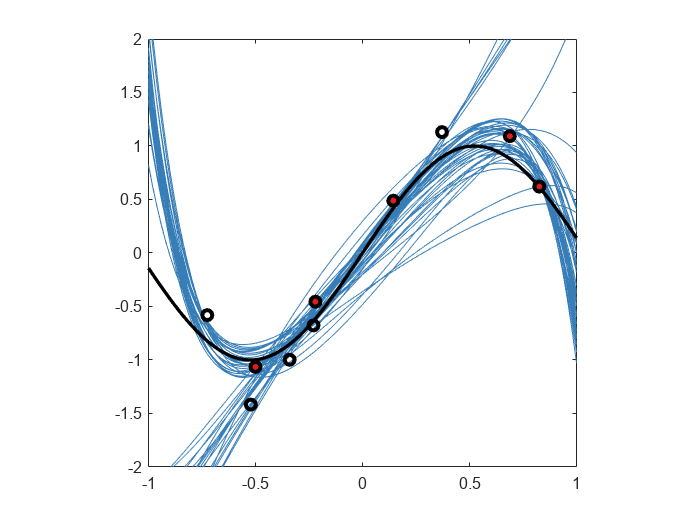

figure
% Create the functions necessary to plot the polynomial 
P = 7;
xVec = linspace(-1,1)';
XVec = ones(length(xVec),P+1);
for j = 1:P
    XVec(:,j+1) = xVec.^j;
end   

for i = 1:BN/10
    
    p = plot(xVec, XVec*theta_boot_sine(:,1:i),...
             xVec, sin(3*xVec), ...
             xSelected(idx(i,:)), ySelected(idx(i,:)), 'k.',...
             xSelected, ySelected, 'ko');

    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    p(i+1).LineWidth = 2; p(i+1).Color = 'k';
    p(i+2).MarkerSize = 10; p(i+2).Color = newcolor(1,:);
    p(i+3).LineWidth = 2.5;

    axis([-1 1 -2 2])
    axis square

    drawnow

end

Show how the estimated statistical properties of the parameters evolve with increasing bootstrap runs

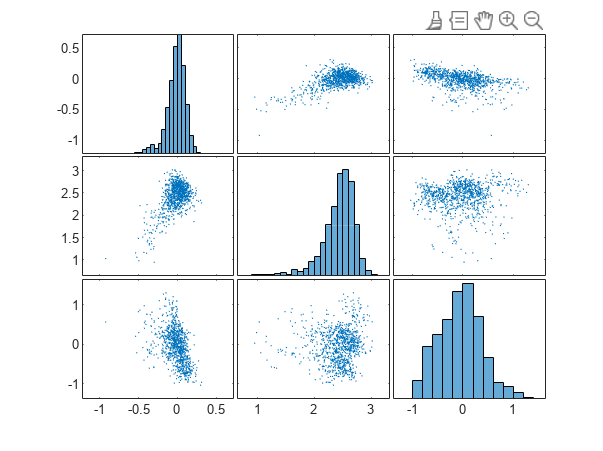

figure
for i = 1:BN/10
    plotmatrix(theta_boot_sine(1:3,1:10*i)');

    drawnow
end

Compare the bootstrap results to the true statistical properties of the parameters

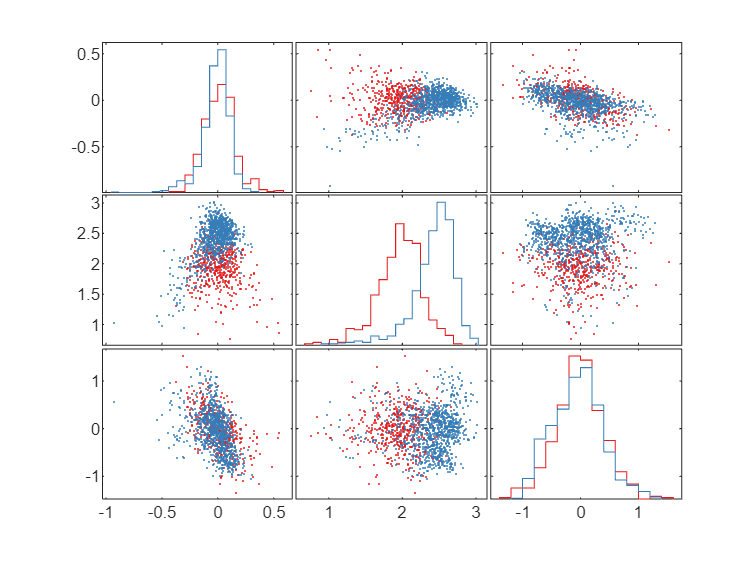

figure
gplotmatrix([theta_reg_sine(1:3,:,I)'; ...
                theta_boot_sine(1:3,:)'], ...
                [],...
               [zeros(length(theta_reg_sine(:,:,I)'),1); ...
                ones(length(theta_boot_sine(1:3,1:10*i)'),1)],...
                newcolor([1,2],:),[],[],'off');